clear
syms L_i L_t L_h
assume(L_i,'positive')
assume(L_t,'positive')
assume(L_h,'positive')
syms x y theta_t phi
assume(x,'real')
assume(y,'real')
assume(theta_t,'real')
assume(phi,'real')
syms v delta_t delta_i
assume(v,'real')
assume(delta_t,'real')
assume(delta_i,'real')

x_dot = v*cos(theta_t)

$$x\_dot = v\,\cos\left(\theta_{t}\right)$$

y_dot = v*sin(theta_t)

$$y\_dot = v\,\sin\left(\theta_{t}\right)$$

r1 = L_t / tan(delta_t);
r2 = sqrt(r1^2+L_h^2);
r3 = L_i * cos(delta_i) / sin(atan(L_h/r1) + phi + delta_i);
theta_t_dot = (v / r1);
vh = (theta_t_dot) * r2;
theta_i_dot = -(vh / r3);
phi_dot = theta_i_dot - theta_t_dot

$$phi\_dot = -\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}-\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\tan\left(\delta_{t}\right)\,\sqrt{\frac{{L_{t}}^{2}}{{\tan\left(\delta_{t}\right)}^{2}}+{L_{h}}^{2}}}{L_{i}\,L_{t}\,\cos\left(\delta_{i}\right)}$$

phi_dot_conf = subs(phi_dot,[v L_t L_h L_i],[-1 2 0.5 1])

$$phi\_dot\_conf = 0.5000\,\tan\left(\delta_{t}\right)+\frac{0.5000\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(0.2500\,\tan\left(\delta_{t}\right)\right)\right)\,\tan\left(\delta_{t}\right)\,\sqrt{\frac{4}{{\tan\left(\delta_{t}\right)}^{2}}+0.2500}}{\cos\left(\delta_{i}\right)}$$

## Compare

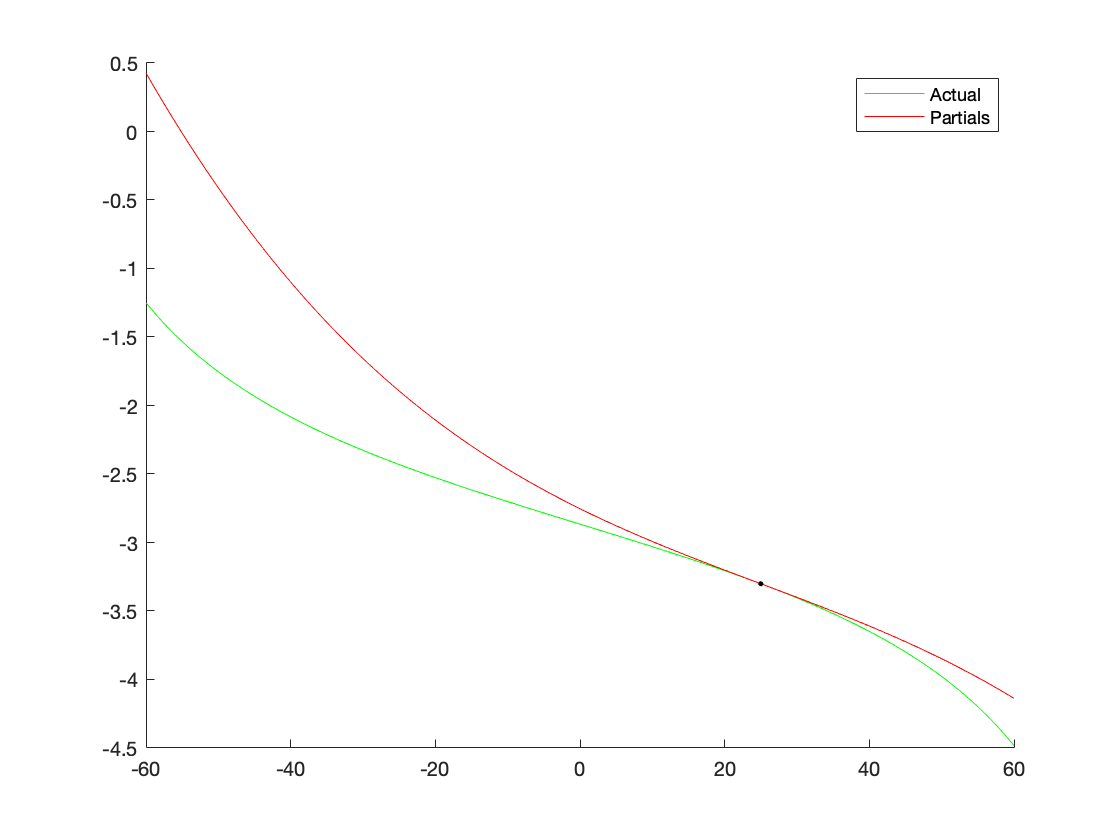

phi_dots_act = zeros(100,1);
phi_dots_est = zeros(100,1);
delta_is = linspace(-pi/3,pi/3,100);

% Set delta_t and phi
delta_t_v = deg2rad(105);
phi_v = deg2rad(90);
phi_dot_of_di = subs(phi_dot_conf,[delta_t,phi],[delta_t_v,phi_v]);
n1 = diff(phi_dot_of_di,delta_i);
n3 = diff(diff(n1,delta_i));

% Set delta_i_0
delta_i_0 = deg2rad(25);
n1 = subs(n1,delta_i,delta_i_0);
n3 = subs(n3,delta_i,delta_i_0);
phi_dot_0 = subs(phi_dot_of_di,delta_i,delta_i_0);

for i = 1:100
    delta_i_v = delta_is(i);
    phi_dots_act(i) = subs(phi_dot_of_di,delta_i,delta_i_v);
%     phi_dots_est(i) = phi_dot_0 + n1*(delta_i_v - delta_i_0);
    phi_dots_est(i) = phi_dot_0 + n1*(delta_i_v - delta_i_0) + n3/6*(delta_i_v - delta_i_0)^3;
end

figure(2), clf, hold on
plot(rad2deg(delta_is), phi_dots_act,'g')
plot(rad2deg(delta_is), phi_dots_est,'r')
plot(rad2deg(delta_i_0),phi_dot_0,'.k') 
legend("Actual","Partials")